# **AERO21111 Space Systems - MATLAB Tutorial 1**

#### Task 1 - Initial Value Input

clear;
M_dry = 1000; % unit is kg
delta_V = 1:0.01:2; % unit is km/s
spec_impulse = 200:1:300; % unit is sec

#### Task 2 - Evaluate and plot the two-variable function

figure
[X,Y] = meshgrid(spec_impulse,delta_V)

X =    200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   215   216   217   218   219   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249
   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   215   216   217   218   219   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249
   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   215   216   217   218   219   220   221   222   223   224   225   226   227   228   229   230   231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249
   200   201   202   203   204   205   206   207   208   209   210   211   212   213   214   

Y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1.0100    1

M_fuel = M_dry .* (exp(Y./(X*9.81))-1)

M_fuel =     0.5098    0.5073    0.5048    0.5023    0.4998    0.4974    0.4950    0.4926    0.4902    0.4879    0.4855    0.4832    0.4809    0.4787    0.4765    0.4742    0.4720    0.4699    0.4677    0.4656    0.4635    0.4614    0.4593    0.4572    0.4552    0.4532    0.4511    0.4492    0.4472    0.4452    0.4433    0.4414    0.4395    0.4376    0.4357    0.4339    0.4320    0.4302    0.4284    0.4266    0.4248    0.4231    0.4213    0.4196    0.4179    0.4162    0.4145    0.4128    0.4111    0.4095
    0.5149    0.5124    0.5098    0.5073    0.5048    0.5024    0.4999    0.4975    0.4951    0.4927    0.4904    0.4881    0.4858    0.4835    0.4812    0.4790    0.4768    0.4746    0.4724    0.4702    0.4681    0.4660    0.4639    0.4618    0.4597    0.4577    0.4557    0.4537    0.4517    0.4497    0.4477    0.4458    0.4439    0.4420    0.4401    0.4382    0.4364    0.4345    0.4327    0.4309    0.4291    0.4273    0.4255    0.4238    0.4220    0.4203    0.4186    0.4169    0.4152

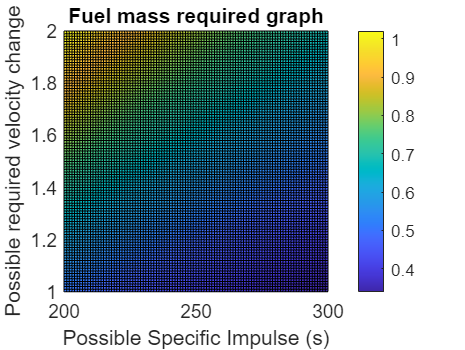

surf(X,Y,M_fuel)
view(2)
title ('Fuel mass required graph')
xlabel ('Possible Specific Impulse (s)')
ylabel ('Possible required velocity change')
colorbar

#### Task 3 - Identifying the Total Launch Mass

As we know from tutorial, Spec_impulse = 230 seconds, total delta_V = 1.3 km/s, and M_dry = 1000 kg.

Therefore,

M_fuel = M_dry .* (exp(delta_V/(Spec_impulse*9.81))-1) = 779.201 kg,

So, 

M_total = 1850 % unit is kg

M_total = 1850

#### Task 4 - Selecting a Launch Vehicle

**Mass Requirements**. 

Table 1 in the tutorial shows that all the launch vehicles can place the required total mass into a polar orbit and so all are potential options at this point.

**Reliability Assessment**. 

Using the values provides the launch reliability of each vehicle has been calculated as follows:

    -    Falcon 9 $\approx 98.4\%$

    -    Ariane 5 $\approx 95.4 \%$

    -    Atlas V $\approx 98.9\%$

    -    Delta IV Medium $\approx 94.9\%$

As the Delta IV has a reliability below $95\%$, albeit on a much lower number of flights and accounting for the fact that most failiures happen early in a vehicles operational lifespan, I have chosen to discount that as an option at this point.

**Environmental Impact**. 

Based on the provided emissions values the remaining launch vehciles have been ranked in accordance with their oupt from low to high:

    -    CO2 emissions: 

                 1. Ariane 5

                 2. Atlas V 

                 3. Falcon 9

    -   H2O emissions:

                1. Ariane 5

                2. Atlas 5

                3. Falcon 9

And so it is clear that the Ariane 5 is the least polluting of the remaining launchers.

**Launch Site Selection**. 

The required orbital inclination of $66^0$ is achievable from all launch sites, however as it is in a prograde orbit this will likely require the initial direction of travel to be to the North East from the launch site to minimise launcher fuel expendature. This reduces the avaiable sites to:

    -    Kennedy Space Centre (CCAFS)

    -    Guiana Space Centre (FRGUI)

    -    Baikonur Cosmodrome (TYMSC)

The remaining launch vehicle options are operated by different states and so this limits the launch options as follows:

    -    Ariane 5: Guiana Space Centre (ESA)

    -    Atlas V: Kennedy Space Centre (United States)

    -    Falcon 9: Kennedy Space Centre (United States)

None of these vehicles are operated by the Russian Federation and so Baiknour Cosmodrome is discounted at this point.

A launch vehicle receives a boost from the Earth's rotation that increases in relation to the equatorial proximity of the launch site. In this case Guiana is the closest to the equator and so would receive the largest boost, although Kennedy would also receive some benefit to a lower factor.

**Final Launch Vehicle Selection**

Although the Falcon 9 and Atlas V both attain a greater reliability score than Ariane 5, this latter vehicle comes out on top in the analysis of environmental impact and launch site selection. Therefore the ESA Ariane 5 operating from Guiana Space Centre has been chosen as the preferred launch vehicle for the Sentinal-6B spacecraft based on these criteron.

# **AERO21111 Space Systems - MATLAB Tutorial 2**

### Task 1 - Define the various inputs and physical constants

A_surf = 3.35 % unit is m^2

A_surf = 3.3500

A_total = 3.35*6 % Assume this aircraft is a cube, and its unit is m^2

A_total = 20.1000

emittance = 0.77

emittance = 0.7700

a_s = 0.46  % absorptance

a_s = 0.4600

a_r = 0.3 % Earth albedo

a_r = 0.3000

sigma = 5.67 * 10^(-8) % Stephan-Boltzmann constant, unit is W*m^-2*K^-4

sigma = 5.6700e-08

R_E = 6371 * 10^(3) % Radius of Earth, unit is m

R_E = 6371000

h = 1336 * 10^(3) % altitude, unit is m

h = 1336000

q_s = 1400 % Solar radiation flux, unit is W*m^-2

q_s = 1400

q_e = 240 % Earth radiation flux, unit is W*m^-2

q_e = 240

P_sun = 1000 % heat dissipated by the spacecraft during sunlit phases

P_sun = 1000

P_eclipse = 500 % heat dissipated during eclipse 

P_eclipse = 500

c_p = 900 % specific heat capacity, unit is J*kg^-1*K^-1

c_p = 900

u = 3.986 * 10^14 % Standard gravitational parameter of Earth, unit is m^3*s^-2

u = 3.9860e+14

T_i = 263.15 % initial tempture, unit is K

T_i = 263.1500

### Task 2 - Find the equation of Thermal time constant, Equilibrium temperatures

#### Thermal time constant Equation:


$$\tau_t =\frac{mc_p }{\varepsilon \sigma A}$$


#### Equilibrium Temperatures:


$$T_{\textrm{eq}} =\sqrt[4]{\frac{Q_{\textrm{in}} }{\varepsilon \sigma A_{\textrm{total}} }}$$


#### Q_in = Q_solar + Q_albedo + Q_earth + Q_power

R_R = h/R_E

R_R = 0.2097

F12 = 1/(1+R_R)^2 % Assume cos(theta) = 1 here

F12 = 0.6834

Q_solar = q_s * a_s * A_surf

Q_solar = 2.1574e+03

Q_albedo = q_s * a_r * a_s * A_surf * F12 % We assume the angle between s/c and sun is 0, and it is a coplanar orbit.

Q_albedo = 442.2791

Q_earth = q_e * emittance * A_surf * F12 

Q_earth = 423.0496

Thermal_time_constant = (M_total * c_p)/(sigma * emittance * A_total) %Thermal time constant equation

Thermal_time_constant = 1.8973e+12

#### Task 3 - Determine the eclipse duration for the satellite.

T = 2 * pi * ((R_E+h)^3/u)^(1/2) % Entire Period of the orbit

T = 6.7335e+03

theta = asind(R_E/(R_E+h)) % results in degrees

theta = 55.7562

f1 = (2*theta)/360 % fraction, theta and 360 are both in degrees

f1 = 0.3098

T_eclipse = T*f1 % Eclipse duration for one period

T_eclipse = 2.0857e+03

#### Task 4 - Calculate the Equilibrium Temperature (T_eq)

Q_in_sun = Q_solar + Q_albedo + Q_earth + P_sun

Q_in_sun = 4.0227e+03

Q_in_ecl = q_e * emittance * A_surf + P_eclipse

Q_in_ecl = 1.1191e+03

T_eq_sun = (Q_in_sun/(emittance * sigma * A_total))^(1/4)

T_eq_sun = 260.2033

T_eq_ecl = (Q_in_ecl/(emittance * sigma * A_total))^(1/4)

T_eq_ecl = 188.9722

#### Task 5 - Calculate the change in temperature over time

P = 20*T % simulation time

P = 1.3467e+05

dt = P/1000 % time steps

dt = 134.6695

% Initialize the Temp and t
array_temp = zeros(1000,1) 

array_temp =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


array_t = zeros(1000,1) % time elapsed

array_t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Temp = T_i

Temp = 263.1500

% Initialize the loop variable
t = 0

t = 0

k = 1

k = 1

while t <= P
    % save T and t to arrays
    array_temp(k) = Temp
    array_t(k) = t
       if (0<=t) && (t<(T-T_eclipse))
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (T<=t) && (t<(T-T_eclipse)+T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (2*T<=t) && (t<(T-T_eclipse)+2*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (3*T<=t) && (t<(T-T_eclipse)+3*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (4*T<=t) && (t<(T-T_eclipse)+4*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (5*T<=t) && (t<(T-T_eclipse)+5*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (6*T<=t) && (t<(T-T_eclipse)+6*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (7*T<=t) && (t<(T-T_eclipse)+7*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (8*T<=t) && (t<(T-T_eclipse)+8*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (9*T<=t) && (t<(T-T_eclipse)+9*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (10*T<=t) && (t<(T-T_eclipse)+10*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (11*T<=t) && (t<(T-T_eclipse)+11*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (12*T<=t) && (t<(T-T_eclipse)+12*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (13*T<=t) && (t<(T-T_eclipse)+13*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (14*T<=t) && (t<(T-T_eclipse)+14*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (15*T<=t) && (t<(T-T_eclipse)+15*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (16*T<=t) && (t<(T-T_eclipse)+16*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (17*T<=t) && (t<(T-T_eclipse)+17*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (18*T<=t) && (t<(T-T_eclipse)+18*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       elseif (19*T<=t) && (t<(T-T_eclipse)+19*T)
            dT = (T_eq_sun^4-Temp^4)/Thermal_time_constant * dt;
       else
            dT = (T_eq_ecl^4-Temp^4)/Thermal_time_constant * dt;
       end
       Temp = Temp + dT;
       t = t + dt;
       k = k+1 % Increment the loop variable;
end

array_temp =   263.1500
         0
         0
         0
         0
         0
         0
         0
         0
         0


array_t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


k = 2

array_temp =   263.1500
  263.1350
         0
         0
         0
         0
         0
         0
         0
         0


array_t =          0
  134.6695
         0
         0
         0
         0
         0
         0
         0
         0


k = 3

array_temp =   263.1500
  263.1350
  263.1201
         0
         0
         0
         0
         0
         0
         0


array_t =          0
  134.6695
  269.3390
         0
         0
         0
         0
         0
         0
         0


k = 4

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
         0
         0
         0
         0
         0
         0


array_t =          0
  134.6695
  269.3390
  404.0085
         0
         0
         0
         0
         0
         0


k = 5

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
         0
         0
         0
         0
         0


array_t =          0
  134.6695
  269.3390
  404.0085
  538.6780
         0
         0
         0
         0
         0


k = 6

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
         0
         0
         0
         0


array_t =          0
  134.6695
  269.3390
  404.0085
  538.6780
  673.3475
         0
         0
         0
         0


k = 7

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
         0
         0
         0


array_t =          0
  134.6695
  269.3390
  404.0085
  538.6780
  673.3475
  808.0170
         0
         0
         0


k = 8

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
         0
         0


array_t =          0
  134.6695
  269.3390
  404.0085
  538.6780
  673.3475
  808.0170
  942.6865
         0
         0


k = 9

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
         0


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
         0


k = 10

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 11

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 12

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 13

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 14

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 15

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 16

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 17

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 18

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 19

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 20

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 21

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 22

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 23

array_temp =   263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 24

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 25

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 26

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 27

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 28

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 29

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 30

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 31

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 32

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 33

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 34

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 35

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 36

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 37

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 38

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 39

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 40

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 41

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 42

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 43

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 44

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 45

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 46

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 47

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 48

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 49

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 50

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 51

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 52

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 53

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 54

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 55

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 56

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 57

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 58

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 59

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 60

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 61

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 62

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 63

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 64

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 65

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 66

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 67

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 68

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 69

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 70

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 71

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 72

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 73

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 74

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 75

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+03 *

         0
    0.1347
    0.2693
    0.4040
    0.5387
    0.6733
    0.8080
    0.9427
    1.0774
    1.2120


k = 76

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 77

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 78

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 79

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 80

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 81

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 82

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 83

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 84

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 85

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 86

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 87

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 88

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 89

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 90

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 91

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 92

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 93

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 94

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 95

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 96

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 97

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 98

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 99

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 100

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 101

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 102

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 103

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 104

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 105

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 106

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 107

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 108

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 109

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 110

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 111

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 112

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 113

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 114

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 115

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 116

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 117

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 118

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 119

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 120

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 121

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 122

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 123

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 124

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 125

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 126

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 127

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 128

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 129

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 130

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 131

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 132

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 133

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 134

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 135

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 136

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 137

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 138

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 139

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 140

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 141

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 142

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 143

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 144

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 145

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 146

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 147

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 148

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 149

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 150

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 151

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 152

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 153

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 154

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 155

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 156

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 157

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 158

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 159

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 160

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 161

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 162

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 163

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 164

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 165

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 166

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 167

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 168

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 169

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 170

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 171

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 172

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 173

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 174

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 175

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 176

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 177

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 178

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 179

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 180

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 181

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 182

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 183

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 184

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 185

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 186

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 187

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 188

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 189

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 190

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 191

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 192

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 193

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 194

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 195

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 196

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 197

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 198

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 199

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 200

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 201

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 202

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 203

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 204

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 205

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 206

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 207

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 208

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 209

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 210

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 211

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 212

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 213

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 214

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 215

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 216

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 217

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 218

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 219

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 220

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 221

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 222

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 223

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 224

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 225

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 226

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 227

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 228

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 229

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 230

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 231

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 232

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 233

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 234

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 235

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 236

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 237

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 238

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 239

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 240

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 241

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 242

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 243

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 244

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 245

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 246

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 247

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 248

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 249

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 250

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 251

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 252

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 253

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 254

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 255

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 256

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 257

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 258

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 259

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 260

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 261

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 262

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 263

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 264

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 265

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 266

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 267

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 268

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 269

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 270

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 271

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 272

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 273

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 274

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 275

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 276

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 277

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 278

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 279

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 280

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 281

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 282

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 283

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 284

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 285

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 286

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 287

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 288

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 289

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 290

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 291

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 292

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 293

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 294

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 295

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 296

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 297

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 298

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 299

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 300

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 301

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 302

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 303

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 304

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 305

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 306

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 307

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 308

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 309

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 310

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 311

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 312

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 313

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 314

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 315

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 316

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 317

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 318

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 319

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 320

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 321

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 322

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 323

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 324

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 325

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 326

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 327

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 328

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 329

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 330

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 331

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 332

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 333

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 334

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 335

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 336

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 337

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 338

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 339

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 340

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 341

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 342

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 343

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 344

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 345

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 346

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 347

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 348

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 349

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 350

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 351

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 352

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 353

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 354

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 355

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 356

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 357

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 358

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 359

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 360

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 361

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 362

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 363

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 364

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 365

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 366

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 367

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 368

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 369

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 370

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 371

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 372

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 373

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 374

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 375

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 376

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 377

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 378

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 379

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 380

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 381

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 382

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 383

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 384

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 385

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 386

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 387

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 388

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 389

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 390

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 391

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 392

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 393

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 394

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 395

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 396

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 397

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 398

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 399

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 400

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 401

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 402

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 403

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 404

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 405

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 406

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 407

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 408

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 409

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 410

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 411

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 412

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 413

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 414

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 415

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 416

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 417

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 418

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 419

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 420

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 421

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 422

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 423

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 424

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 425

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 426

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 427

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 428

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 429

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 430

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 431

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 432

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 433

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 434

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 435

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 436

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 437

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 438

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 439

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 440

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 441

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 442

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 443

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 444

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 445

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 446

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 447

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 448

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 449

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 450

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 451

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 452

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 453

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 454

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 455

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 456

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 457

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 458

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 459

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 460

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 461

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 462

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 463

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 464

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 465

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 466

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 467

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 468

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 469

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 470

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 471

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 472

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 473

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 474

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 475

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 476

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 477

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 478

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 479

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 480

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 481

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 482

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 483

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 484

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 485

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 486

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 487

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 488

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 489

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 490

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 491

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 492

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 493

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 494

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 495

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 496

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 497

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 498

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 499

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 500

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 501

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 502

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 503

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 504

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 505

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 506

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 507

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 508

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 509

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 510

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 511

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 512

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 513

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 514

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 515

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 516

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 517

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 518

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 519

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 520

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 521

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 522

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 523

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 524

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 525

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 526

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 527

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 528

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 529

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 530

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 531

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 532

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 533

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 534

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 535

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 536

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 537

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 538

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 539

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 540

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 541

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 542

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 543

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 544

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 545

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 546

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 547

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 548

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 549

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 550

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 551

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 552

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 553

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 554

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 555

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 556

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 557

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 558

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 559

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 560

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 561

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 562

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 563

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 564

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 565

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 566

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 567

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 568

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 569

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 570

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 571

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 572

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 573

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 574

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 575

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 576

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 577

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 578

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 579

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 580

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 581

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 582

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 583

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 584

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 585

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 586

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 587

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 588

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 589

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 590

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 591

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 592

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 593

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 594

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 595

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 596

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 597

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 598

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 599

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 600

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 601

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 602

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 603

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 604

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 605

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 606

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 607

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 608

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 609

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 610

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 611

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 612

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 613

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 614

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 615

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 616

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 617

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 618

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 619

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 620

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 621

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 622

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 623

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 624

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 625

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 626

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 627

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 628

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 629

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 630

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 631

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 632

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 633

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 634

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 635

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 636

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 637

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 638

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 639

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 640

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 641

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 642

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 643

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 644

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 645

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 646

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 647

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 648

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 649

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 650

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 651

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 652

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 653

array_temp = 1000×1
  263.1500
  263.1350
  263.1201
  263.1053
  263.0905
  263.0758
  263.0612
  263.0467
  263.0322
  263.0178


array_t = 1000×1
1.0e+04 *

         0
    0.0135
    0.0269
    0.0404
    0.0539
    0.0673
    0.0808
    0.0943
    0.1077
    0.1212


k = 654

#### Task 6 - Plot the graph

% Plot the temperature over time
figure;
plot(array_t, array_temp, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Temperature (K)');
title('Satellite Temperature vs Time');
yline(310,'k--')
yline(255,'k--')

% Highlight eclipse periods on the graph
eclipse_times = [T-T_eclipse,T,2*T-T_eclipse,2*T,3*T-T_eclipse,3*T,4*T-T_eclipse,4*T,5*T-T_eclipse,5*T,6*T-T_eclipse,6*T,7*T-T_eclipse,7*T,8*T-T_eclipse,8*T,9*T-T_eclipse,9*T,10*T-T_eclipse,10*T,11*T-T_eclipse,11*T,12*T-T_eclipse,12*T,13*T-T_eclipse,13*T,14*T-T_eclipse,14*T,15*T-T_eclipse,15*T,16*T-T_eclipse,16*T,17*T-T_eclipse,17*T,18*T-T_eclipse,18*T,19*T-T_eclipse,19*T,20*T-T_eclipse,20*T]
hold on;
for i = 1:2:length(eclipse_times)
    area([eclipse_times(i), eclipse_times(i+1)], [320, 320], 'FaceColor', [0.9 0.9 0.9], 'EdgeColor', 'none');
end
hold off

% Add legend
legend('Temperature', 'Temperature Bound', 'Location', 'Best')

% Add grid for better readability (optional)
grid on

## Discussion

Sentinel-6B is equipped with a sensitive component that operates best in temperatures between -15°C and 30°C. However, with the current temperature control methods, the spacecraft components will not be able to stay in orbit, as indicated by the graph that was created in the earlier tasks. Thus, there are two ways to modify Sentinel-6B's heat control mechanism. Either modify the coating material of the spacecraft to increase its emissivity and absorptivity, or install a heater that operates exclusively during eclipses. 

### Conclusion